# Mass damper spring system

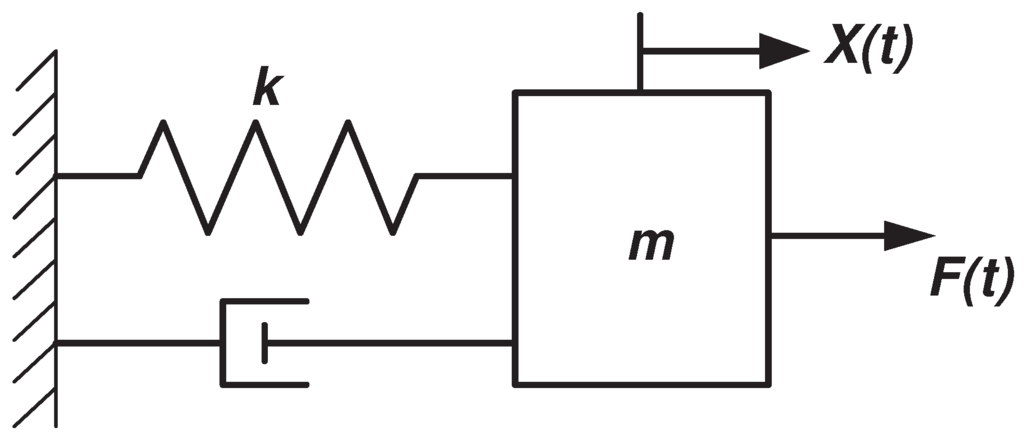

We will consider the following system. This system has the following state space representation:


$$\pmatrix{\dot{x} \cr \ddot{x}} = 
\pmatrix{0 & 1 \cr \frac{-k}{M} & \frac{-f_v}{M}}
\pmatrix{x \cr \dot{x}} +
\pmatrix{0 \cr \frac{1}{M}} u$$


k = 1;
M = 1;
f = 1;
A = [0 1 ; -k/M -f/M];
B = [0 ; 1/M];
C = [1 0 ; 0 1];
D = [];
sys_mds_c = ss(A,B,C,D);

## Impulse response

For this example we will consider data generated by the impulse response of this system.

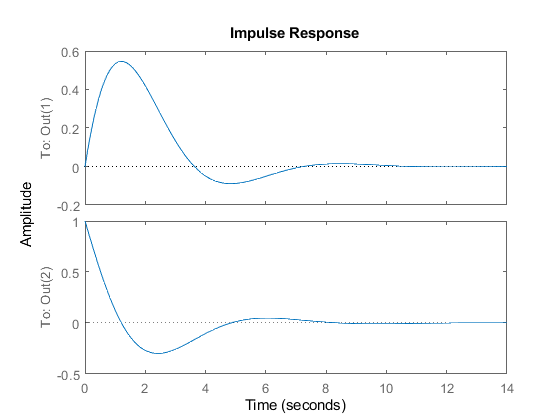

impulse(sys_mds_c)

[y_impulse, t_impulse, x_impulse] = impulse(sys_mds_c);

### Defining the data

We will first consider all `150` datapoints generated. Since we are considering the impulse responce we have that our input is infinitly small and thus bassically non existing. Because of this we can only use the impulse respons to find the `A` matrix of the system.

X_impulse = x_impulse.';

### System identification

We can check if the data is informative for system identification by using `[bool, A, B] = isIdentifiable(X, U)`. For this to be the case we need that the data is full rank, i.e.:


$$rank \pmatrix{X_- \cr U_-} = n + m$$


Since we use the impulse function we know that $U_-
$ is empty and $m$ is zero. Hence we only need to find 2 linearly independant columns in our data points. From this we can see that the use of 150 data points is a bit eccesive, hence we also consider some cases below where we reduce the amount of data points.

disp("Is the data informative for system identification?");

Is the data informative for system identification?


[bool, A_impulse] = isInformIdentification(X_impulse)

bool = logical
   1


A_impulse =     0.9959    0.0879
   -0.0879    0.9080


We will use the received A matrix to verify the data.

#### Verifying results

We can check the validity of the results by comparing them against the continuous time version of the system. To get the continuous time system we use the [`sysc = d2c(sysd)`](https://nl.mathworks.com/help/control/ref/d2c.html#d122e34030) function provided by matlab. (We can find the timestep of the data by inspecting the `t` array that was returned by the impuls function)

disp("What does the obtained system look like in continuous time form?")

What does the obtained system look like in continuous time form?


sys_impulse_d = ss(A_impulse, [], C, D, t_impulse(2));
sys_impulse_c = d2c(sys_impulse_d)

sys_impulse_c =
 
  A = 
              x1         x2
   x1  -3.24e-15          1
   x2         -1         -1
 
  B = 
     Empty matrix: 2-by-0
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
     Empty matrix: 2-by-0
 
Continuous-time state-space model.



As we can see we can retreive all the information about the $A
$ matrix using the imulse response of the system. To also get the $B$ matrix we need the step response as well.

### Stability

We can also check if the data is informative for stability. Looking at the plot of the impulse response, we would expect this to be the case. We can verify this by using the function `bool = isInformStable(X)`.

disp("Is the data informative for stability?");

Is the data informative for stability?


disp(isInformStable(X_impulse));

   1



## Step response

As noted above, we will use the step response to retreive the $A$ and $B$ matrix discribing the system.

### Defining data

We will start by considering all 150 data points generated by the step function. We will see later on that this is ecsessive and that we can use less points for the same result.

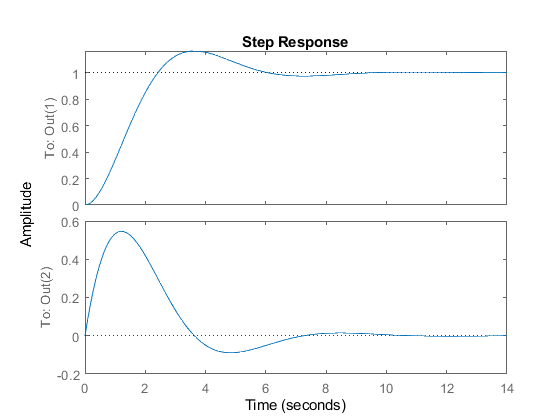

step(sys_mds_c)

[y_step, t_step, X_step] = step(sys_mds_c);
U_step = ones(1,149);
X_step = x_step.';

### System identification

We will again use the `[bool, A, B] = isIdentifiable(X, U)` function to see if the data is informative for system identification.

disp("Is the data informative for system identification?");

Is the data informative for system identification?


[bool, A_step, B_step] = isInformIdentification(X_step, U_step)

bool = logical
   1


A_step =     0.9959    0.0879
   -0.0879    0.9080


B_step =     0.0041
    0.0879


As we can see the data is indeed informative for system identification.

#### Verifying results

We will once again check the validity of the data by first converting the system back to a continuous time system using the [`sysc = d2c(sysd)`](https://nl.mathworks.com/help/control/ref/d2c.html#d122e34030) function provided by matlab, using the same timestep as the data, namely `t_step(2)`.

disp("What does the obtained system look like in continuous time form?")

What does the obtained system look like in continuous time form?


sys_step_d = ss(A_step, B_step, C, D, t_step(2));
sys_step_c = d2c(sys_step_d)

sys_step_c =
 
  A = 
              x1         x2
   x1  4.822e-15          1
   x2         -1         -1
 
  B = 
              u1
   x1  3.466e-15
   x2          1
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



As we can see we get the valid $A$ and $B$ matrix (up to working precision). Thus we can conclude that the impulse response in insufficient for finding the $B$ matrix of the system. It is however still informative for identification of the `A` matrix. The step responce however is sufficient for finding both the $A$ and $B$ matrix of the system.

## Controllability

In this section we will see if the data is informative for controllability. We can check this using the `bool = isControllable(X)` function.

disp("The data is informative for controllability?");

The data is informative for controllability?


disp(isInformControllable(X_step));

   1



As we can see the data is informative for controllability. We can verify this by means of the reachability matrix of the actual system.

disp("The system is controllable?");

The system is controllable?


disp(rank([B A*B]) == 2);

   1



## Stabilisability

In this section we will see if the data is informative for stabilizability. We can check if the data is informative for stabilizability by using the function `bool = isStabilisable(X)`.

disp("The data is informative for system stabilisability?");

The data is informative for system stabilisability?


disp(isInformStabilisable(X_step))

   1



As expected, the data is informative for stabilisability. This is what we would expect since if a system is controllable it should also be stabilisable.

## State feedback

Since our system is controllable, we might want to find a state feedback controller, in this example it is unneccesary since the system is already stable, but lets assume we are not aware of this. To find a full state feedback controller we can use the function `[bool, K, diagnostics] = StateFeedbackYalmip(X, U, tolerance, options)`.

[bool, K, diagnostics] = StateFeedbackYalmip(X_step, U_step);

Since we have that the data is also informative for system identification, we can verify the result.

disp("Is the data informative for state feedback?");

Is the data informative for state feedback?


disp(bool);

   1



disp("The eigenvalues of A+BK are:");

The eigenvalues of A+BK are:


disp(eig(A_step + B_step * K));

   0.9996 + 0.0182i
   0.9996 - 0.0182i



disp("Their magnitude is:");

Their magnitude is:


disp(abs(eig(A_step + B_step * K)));

    0.9998
    0.9998



Thus the provided controller is indeed a stabilizing controller, al be it a slow one. Currently it is not possible to place the poles for the given controller.

## Deadbeat Control

Since our system is controllable, we might want to find a deadbeat controller. A deadbeat controller is a controller that brings the system to a stable state in `1` iterarion. This is done by finding a controller that assigns the eigenvalues of the closed loop system to zero. To do this we will use the function `[bool, K] = isInformDeadbeatControl(X, U)`.

# See problems.txt

%[bool, K] = isInformDeadbeatControl(X_step(:,1:5), U_step(:,1:4))
%disp("Is the data informative for deadbeat control?");
%disp(bool);
%disp("What is the corresponding controller?");
%disp(K);
%disp("The eigenvalues of the closed loop system are:")
%disp(eig(A_step + B_step * K))

## How much data is needed and what is the precision

We will now look at how much data we need for system identification, for this we will check the first `n` entries of the step response data where `n` is from `1` to `20`. We will also use these results to check the consistency of the result based on the amount of data provided.

n = 149;
valid = [];
a11 = []; a12 = []; a21 = []; a22 = [];
b1  = []; b2  = [];
for idx = 1:n
    X_temp = X_step(:,1:idx+1);
    U_temp = U_step(:,1:idx);
    if isInformIdentification(X_temp, U_temp)
        valid = [valid idx];
        [~, A_temp, B_temp] = isInformIdentification(X_temp, U_temp);
        a11 = [a11 A_temp(1,1)];
        a12 = [a12 A_temp(1,2)];
        a21 = [a21 A_temp(2,1)];
        a22 = [a22 A_temp(2,2)];
        b1  = [b1  B_temp(1)];
        b2  = [b2  B_temp(2)];
    end
end

From this we can inspect the `valid` array and see for how many data points the data is informative for system identification. As we noted earlier, we only needed `3`  linearly independant collumns, which where the 1st, 2nd and 3rd collumn in this case.

disp("How many data points are needed for system identification?:")

How many data points are needed for system identification?:


valid

valid =      3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52


We can also verify that the received $A
$ matrix is consistent. To do this we will normilize out `a11, a12, ..., b2` with the actual $A$ and $B$ matrix and plot the error.

***ERROR: plot legend not working correct, fix later.***

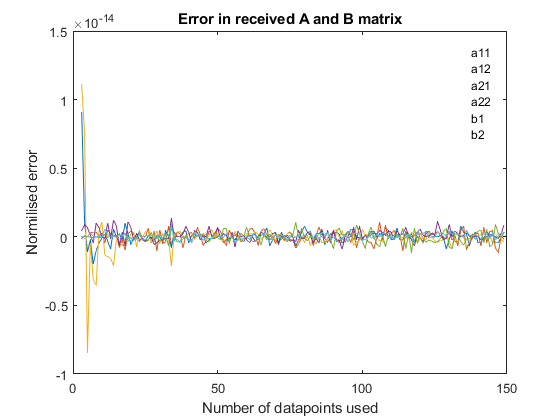

x = valid;
plot(x, a11 - sys_mds_d.A(1,1), 'DisplayName', 'a11');
hold on
plot(x, a12 - sys_mds_d.A(1,2), 'DisplayName', 'a12');
plot(x, a21 - sys_mds_d.A(2,1), 'DisplayName', 'a21');
plot(x, a22 - sys_mds_d.A(2,2), 'DisplayName', 'a22');
plot(x, b1  - sys_mds_d.B(1),   'DisplayName', 'b1');
plot(x, b2  - sys_mds_d.B(2),   'DisplayName', 'b2');
title("Error in received A and B matrix");
xlabel("Number of datapoints used");
ylabel("Normilised error");
legend;
hold off

As we can see the received $A$ and $B$ matrix are consistent up to machine precision.

## What is the impact of sampling moment?

We will now consider what happence when we skip the first few entries. We want that the result stays consistent independant of when we sample the system.

n = 100;
valid = [];
a11 = []; a12 = []; a21 = []; a22 = [];
b1  = []; b2  = [];
for idx = 1:n
    X_temp = X_step(:,idx:end);
    U_temp = U_step(:,idx:end);
    if isInformIdentification(X_temp, U_temp)
        valid = [valid idx];
        [~, A_temp, B_temp] = isInformIdentification(X_temp, U_temp);
        a11 = [a11 A_temp(1,1)];
        a12 = [a12 A_temp(1,2)];
        a21 = [a21 A_temp(2,1)];
        a22 = [a22 A_temp(2,2)];
        b1  = [b1  B_temp(1)];
        b2  = [b2  B_temp(2)];
    end
end

We can now plot this data to see what happence with the error.

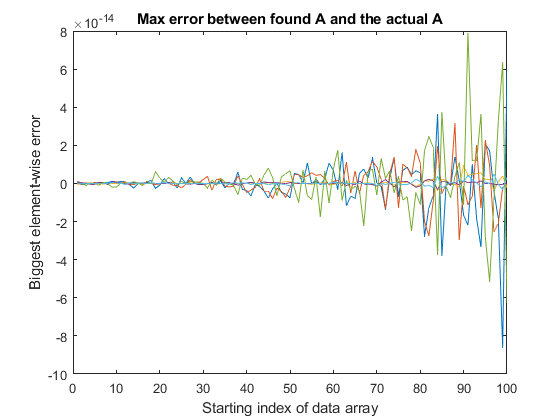

x = valid;
plot(x, a11 - sys_mds_d.A(1,1), 'DisplayName', 'a11');
hold on
plot(x, a12 - sys_mds_d.A(1,2), 'DisplayName', 'a12');
plot(x, a21 - sys_mds_d.A(2,1), 'DisplayName', 'a21');
plot(x, a22 - sys_mds_d.A(2,2), 'DisplayName', 'a22');
plot(x, b1  - sys_mds_d.B(1),   'DisplayName', 'b1');
plot(x, b2  - sys_mds_d.B(2),   'DisplayName', 'b2');
title(gca,"Max error between found A and the actual A")
xlabel('Starting index of data array')
ylabel('Biggest element-wise error')
%legend;
hold off

As we can see the error is relativly small but increasing. This is due to noice introduced by floating point inaccuracies that keep compounding.